clear
clc
v = VideoReader('FINGER_PULSE_TRIMMED.mp4');

i=1;
while hasFrame(v)
    RGBframes = readFrame(v);
    GRAYframes = rgb2gray(RGBframes);
    BWvideo(:,:,i)=GRAYframes;
%     imshow(GRAYframes);
%     title(sprintf('Current Time = %.3f sec', v.CurrentTime));
%     pause(2/v.FrameRate);
    i=i+1;
end
%%%%%

Obtener grafica del brillo de cada frame. Est brillo se calcula con un promedio del brillo de todos los pixeles)

for i=1:v.NumFrames
    means(i)=mean2(BWvideo(:,:,i)); %mean of every frame 
end
t=linspace(0,v.Duration,v.NumFrames);
means=-means;

means =   -53.1308  -53.1478  -53.2258  -53.3586  -53.5015  -53.6279  -53.7707  -53.9358  -54.0763  -54.1519  -53.8624  -52.7783  -52.2329  -52.2030  -52.3265  -52.5791  -52.9181  -53.1892  -53.3163  -53.3823  -53.4596  -53.5703  -53.7035  -53.8952  -54.0482  -54.1058  -54.2483  -54.3765  -54.4966  -54.5085  -53.6403  -52.9429  -52.6347  -52.6414  -52.8586  -53.1581  -53.4716  -53.5967  -53.6913  -53.7363  -53.7899  -53.8875  -53.9813  -54.0782  -54.2228  -54.3359  -54.4404  -54.5255  -54.5513  -54.0788


Con la intención de no obtener una componente de DC muy alta en la FFT, se busca eliminar ese offset.

DC_component=mean(means(:));

DC_component = -53.7722

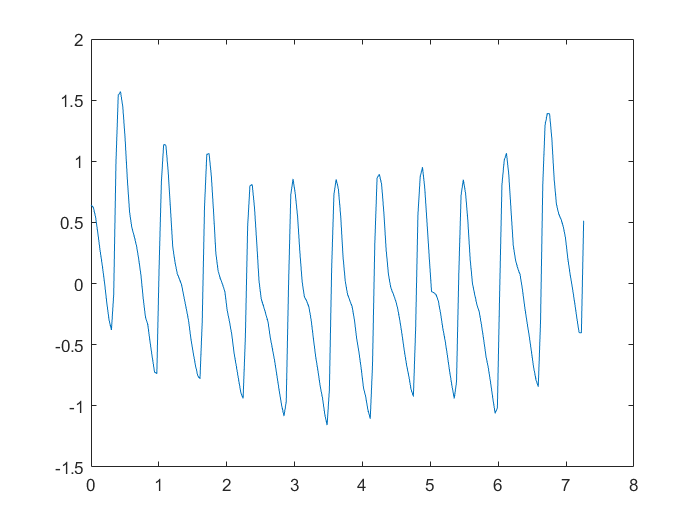

means=means-DC_component;
plot(t,means)

Obtenemos la FFT de la señal y observamos las componentes de frecuencia que son más altas. 

%FFT%
Ts=1/30; %time increment for every second
fs=1/Ts;
L=length(means)

L = 218

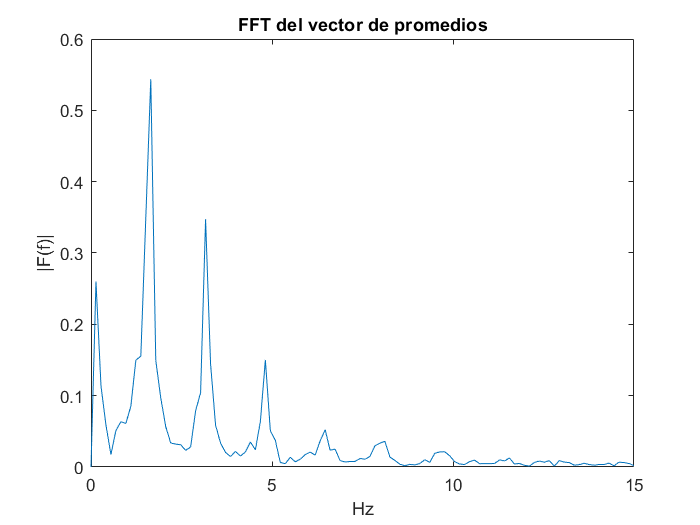

y=fft(means);
P2=abs(y/L);
P1=P2(1:L/2+1);
P1(2:end-1)=2*P1(2:end-1);
f=fs*(0:(L/2))/L;
plot(f,P1)
title('FFT del vector de promedios')
xlabel('Hz')
ylabel('|F(f)|')